# Examples creating metasurface mask files with genGDS

## Example 1: Defining geometry as an image

There are three ways to specify the unit cells geometry with `genGDS`. Let us start with the most general one: a binary image. A binary image is an image of ones and zeros, or, more generally, zero and non-zero pixels. In the metasurface context, we are interested in ones being, usually, the higher-index material, and zeros -- the lower-index one. The input to `genGDS` will be passed through the `round` function to treat any grayscale pixels that might be left from topology optimization. Then, the `bwboundaries` function (Image Processing Toolbox) will be used to find all boundary regions in the image. It supports both numerical and logical matrices and distinguishes only between zero and non-zero pixels. For example, `imread` loads this PNG file as a `unit8` matrix of 0 (black) and 255 (white).

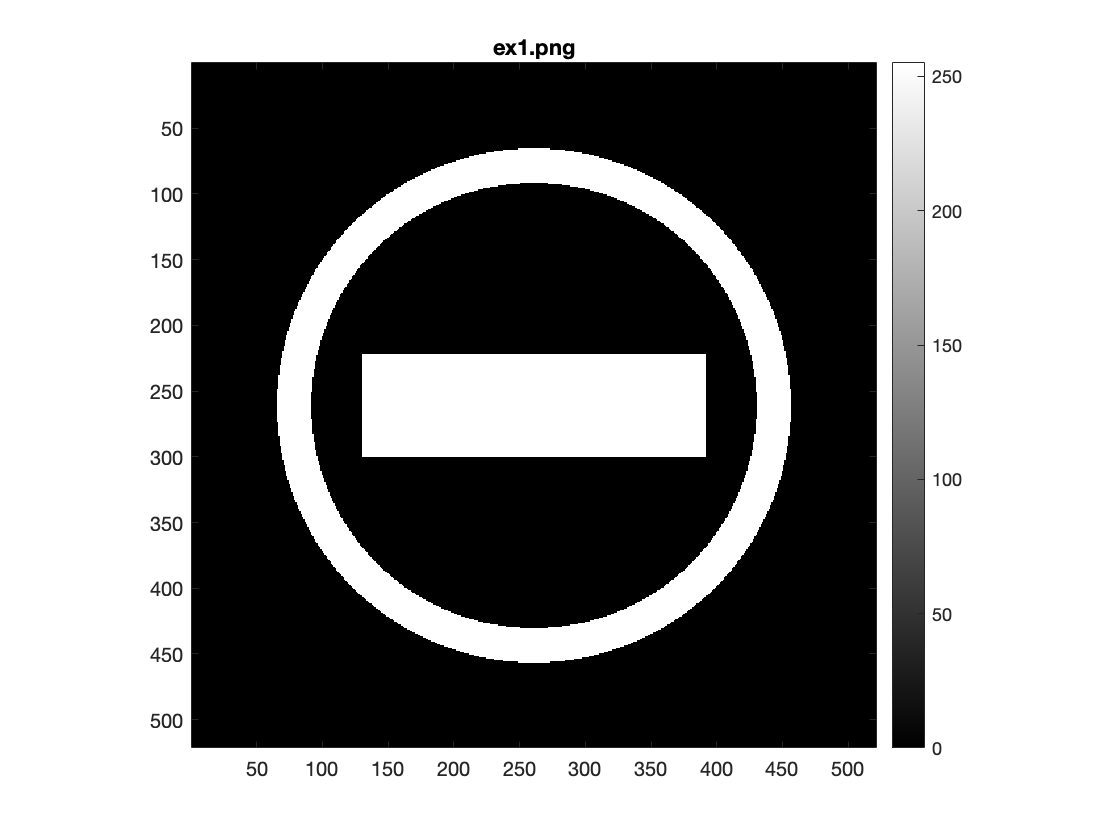

BW = imread('example.png');
imagesc(BW.'), colormap(gray), colorbar, axis equal, axis tight
title('example.png')

Now, we can write a basic .gds file (exclamation point in front of the file name is a signal to the GDSII Toolbox to overwrite the file if it exists):

genGDS('fname', '!ex1_1', 'geom', BW);

Inside `ex1_1.gds`, we will see (screenshot of the KLayout viewer):

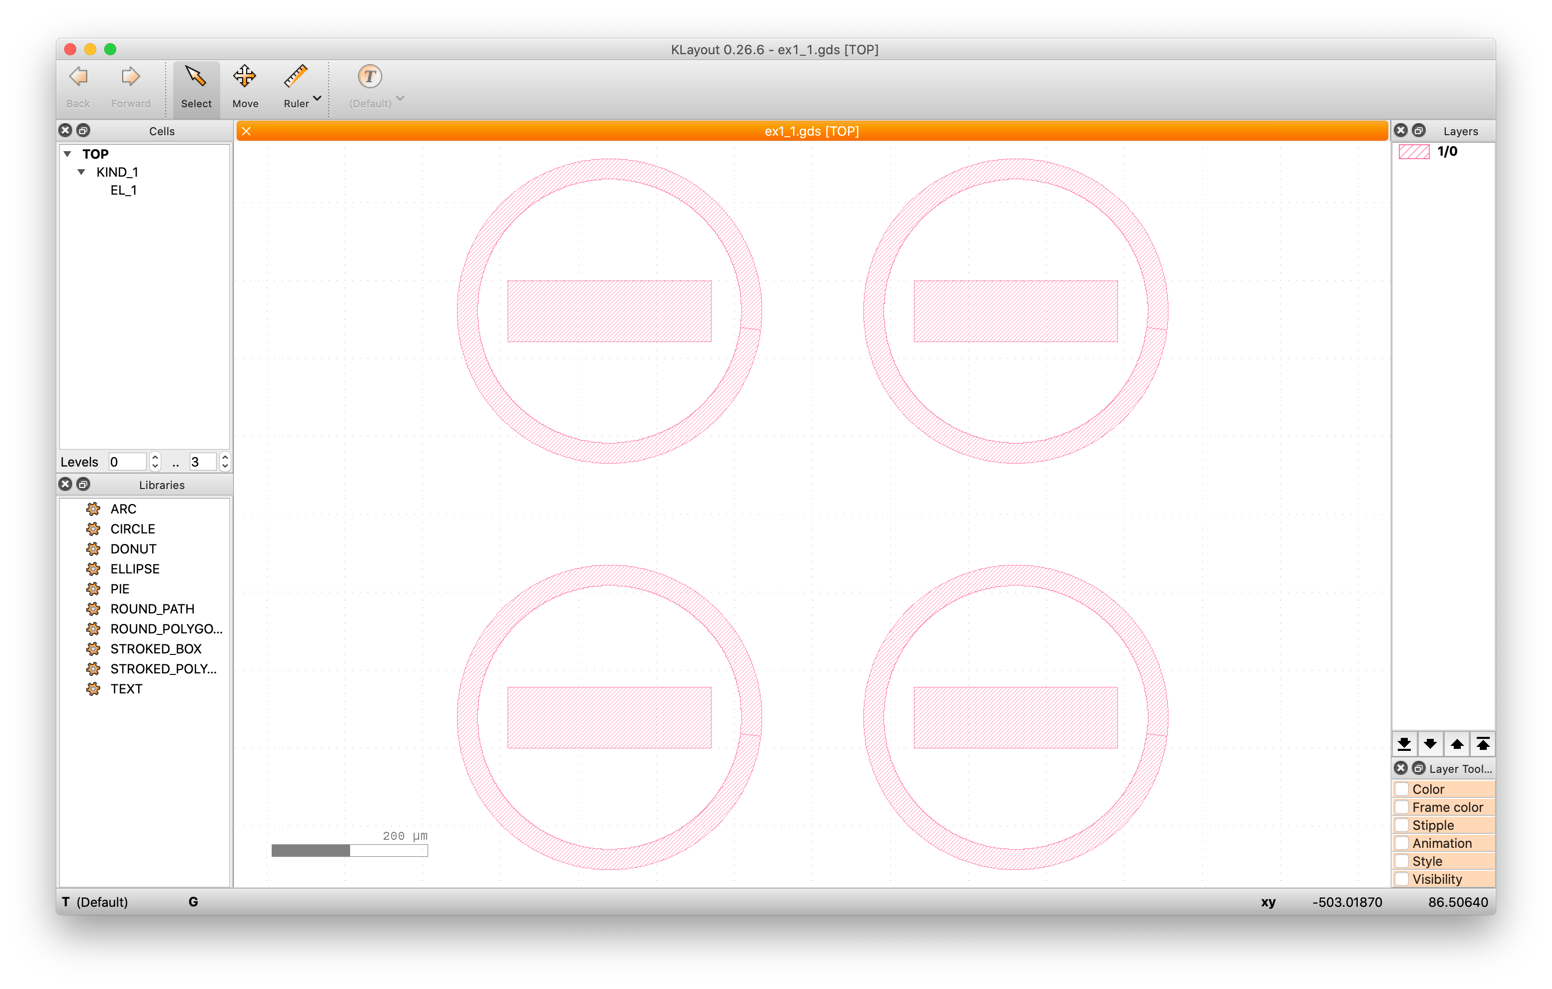

We have four of them, because the default `type` option is `circ2cart`, so they form the smallest circle approximated with rectangular pixels.

Notice the seam on the right. It is there because the gds file format requires a closed contour with no holes, so the inner and the outer boundary have to be connected. The function takes care of the relationship between the boundaries automatically. 

The default value for the `shading` parameter is `'posts'`, i.e. regions with non-zero elements are colored. Let's change the shading to the opposite one – `'holes'`:

genGDS('fname', '!ex1_2', 'geom', BW, 'shading', 'holes');

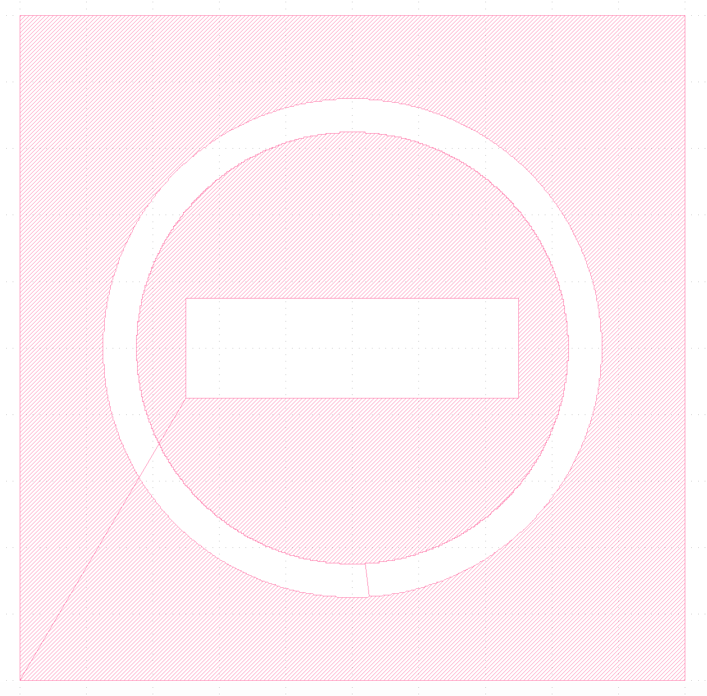

Notice again the line connecting the inner and outer boundaries.

There is an option called `bgd_tiling` that divides the background into smaller adjacent regions. This is also a way to force `genGDS` (actually `gen_gds_structure`) to use GDSII Toolbox's `poly_bool` over `eldiff` (see manual for more details). However, for many cases, including this one, it is not necessary, but for the sake of demonstration, we include it here. This example divides the cell into 4x4 grid. This option requires the 'tiles' to be no smaller than the smallest element. Fox example, it will fail with `bgd_tiling` equal to `5`, since in this case, the rectangle in the middle removes a whole tile (thus creating a 'hole' of more than it's size).

genGDS('fname', '!ex1_3', 'geom', BW, 'shading', 'holes', 'bgd_tiling', 4);

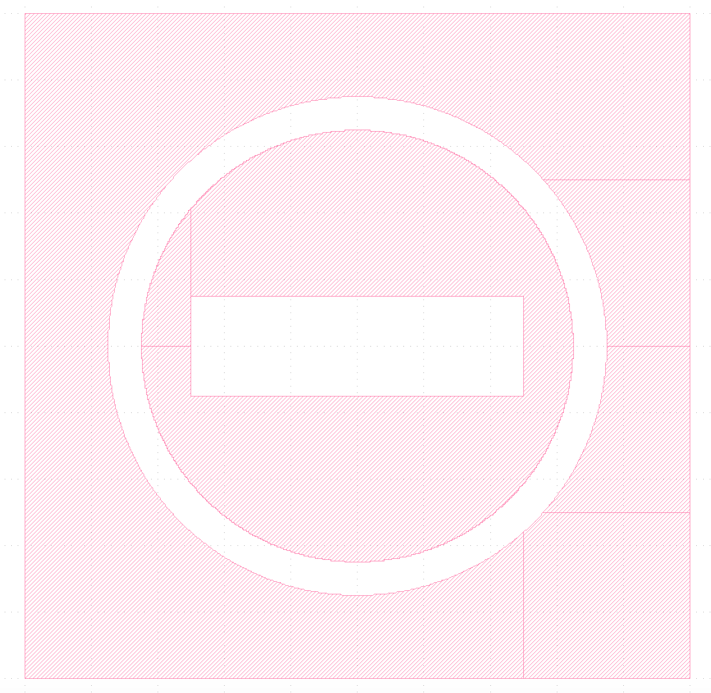

As a more challenging and interesting example, let's try one from Matlab's test images:

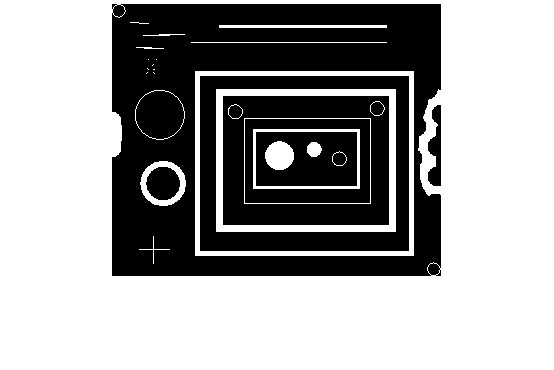

BW = imread('blobs.png');
imshow(BW)

genGDS('fname', '!ex1_4', 'geom', BW.','type','cyl');

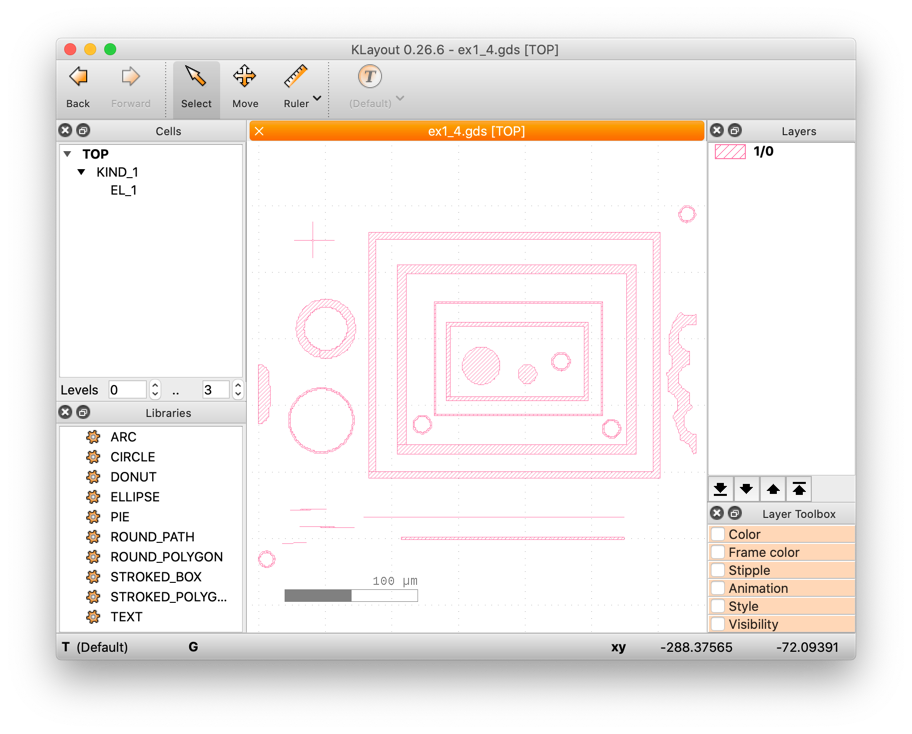

We can easily show a grid of images.

P = size(BW.'); % period, same value as the default one, need for the dimensions
Nx = 5; % number of repetitions in the x dimension
Ny = 3; % in y
genGDS('fname', '!ex1_5', 'geom', BW.', 'period', P, 'type', 'cyl2cart', 'Rmax',[Nx Ny].*P);

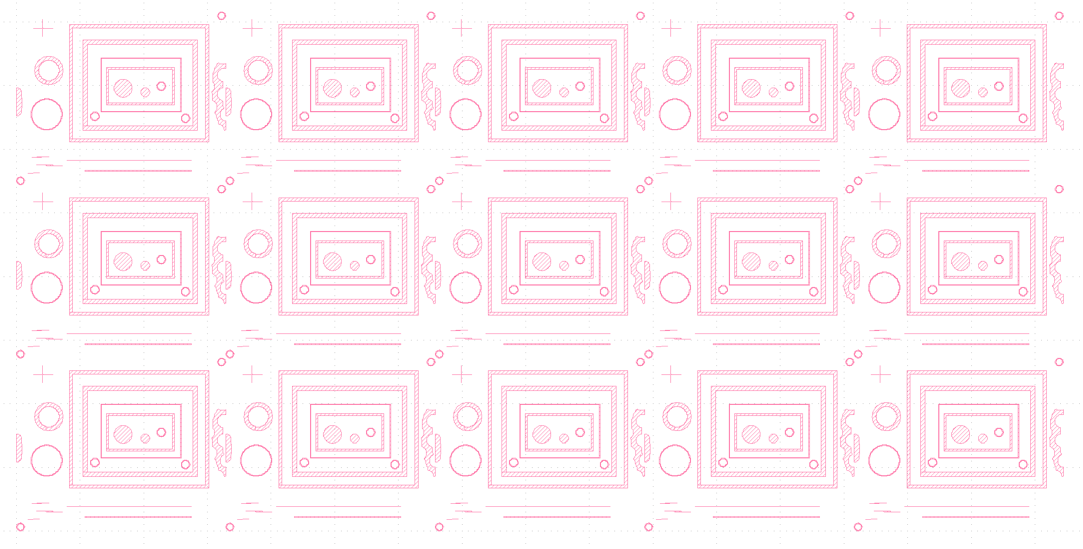

Note that for a single element before we've left the default `type` option `circ2cart`, which means the circular arrangement of the elements, and our was in the center. While for this example, we want to have a 2D array, therefore, we change it to `cyl2cart` (`cyl` would work exactly the same).

On a final note, keep in mind that the image resolution will play a role in the smoothness of the mask. `bwboundaries` returns the coordinates of the border non-zero pixels, which are rectangles, but GDS software just connect them with a line and shades one side, which might cause ragged shapes.

BW = imread('example.png');
BW = imresize(BW, .1); % reduce size to the 10% of the original image
genGDS('fname', '!ex1_6', 'geom', BW);

What we get in the mask file is:

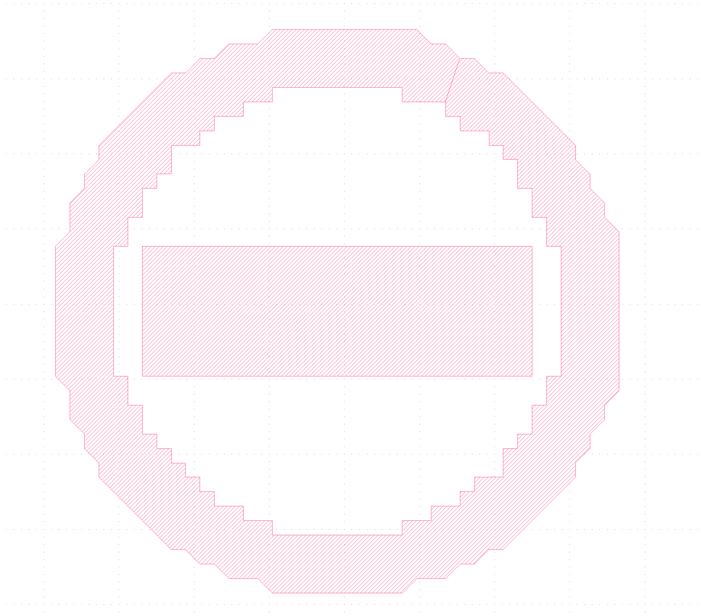

## Example 2: Defining geometry as a boundary

A boundary is usually fetched from an image, or generated by some custom function. For instance, to get the same result as `ex1_1`, we could do

BW = imread('example.png');
[b,~,n,A] = bwboundaries(BW);
genGDS('fname', '!ex2_1', 'geom', b{1}, 'period', size(BW));

Here, we trace a bar from example`.png` provided as an `Nx2` matrix. The period is now a required parameter. Multiple boundaries have to packed in a cell array, which in turn has to placed in a cell of another, to mark a metasurface unit cell consisting of multiple boundaries. For example, to transfer the full image to the mask, the command would be

genGDS('fname', '!ex2_2', 'geom', {b}, 'n', n, 'A', A, 'period',size(BW));

Note that an adjacency matrix is needed to re-create the image, since boundary #3 (inner circle) has to be subtracted from #1 (outer circle).

Let's try putting the second image side-by-side.

BW2 = imread('blobs.png');
BW2 = BW2.'; % first dimension x, second y, different from imshow
BW = imresize(BW, size(BW2,2)/size(BW,2)); % make the images have same height
[b,~,n,A] = bwboundaries(BW); % recalculate for the new size
[b2,~,n2,A2] = bwboundaries(BW2);
genGDS('fname', '!ex2_3', 'geom', {b,b2}, 'n', [n n2], 'A', {A, A2}, 'period',[size(BW);size(BW2)], 'type', 'cyl2cart');

The output is now:

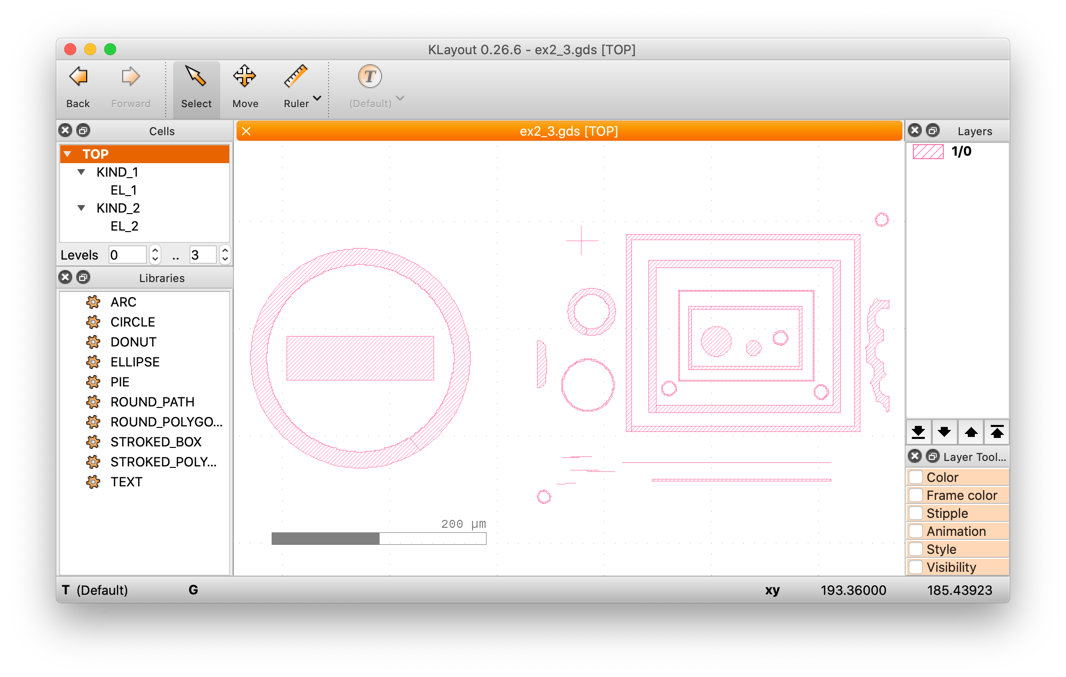

That this is not enough for real cases, since we're not specifying a real period here. 

For example, let's consider a rectangular period that doesn't have the side ratio of either image:

BW = imread('example.png');
[b,~,n,A] = bwboundaries(BW);
P = [200 300]; % e.g. microns
% transform pixel number to coordinates
xGrid = linspace(0, P(1), size(BW, 1)+1);
xGrid = xGrid(2:end).' - xGrid(2)/2; % offset to the center of a pixel
yGrid = linspace(0, P(2), size(BW, 2)+1);
yGrid = yGrid(2:end).' - yGrid(2)/2;
for i = 1:length(b)
    b{i} = [xGrid(b{i}(:,1)), yGrid(b{i}(:,2))];
end
genGDS('fname', '!ex2_4', 'geom', {b}, 'n', n, 'A', A, 'period', P,'type','cyl');

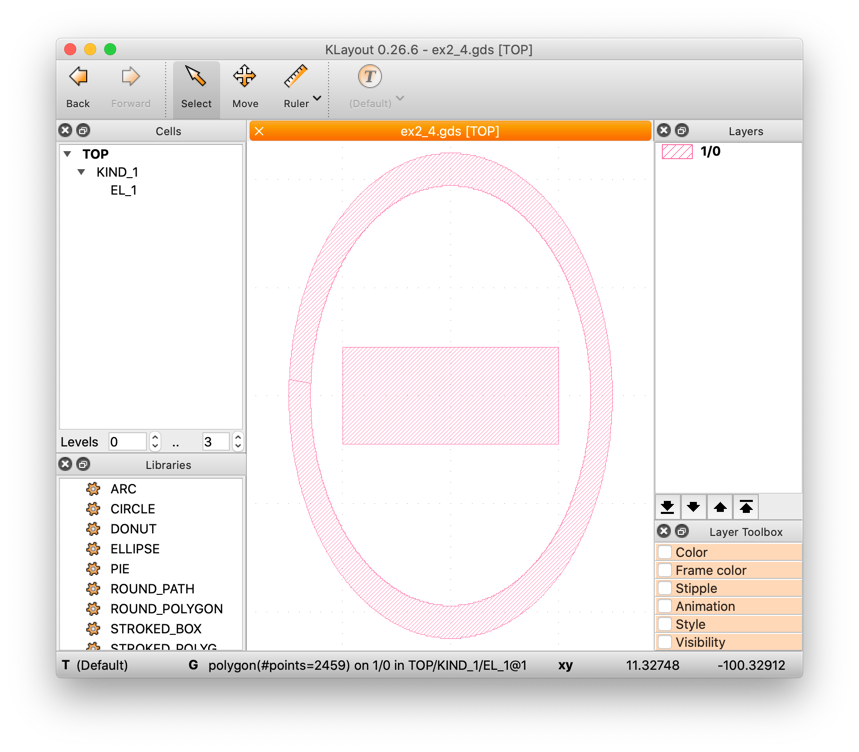

The geometry was scaled proportionally to match `P`. If we didn't put `b` inside the cell of it's own, the three components would be considered as different meta-atoms.

## Example 3: Defining geometry as a struct

Whereas before the focus was on freeform shapes, this section will deal with the cases where a boundary can be approximated with a simple (or not so simple) shape by defining geometric parameters as arguments to a function that produces a boundary. There are two functions that are included in the package: `ellipse`, for elliptical shapes, and `rectbox` for rectangles. 

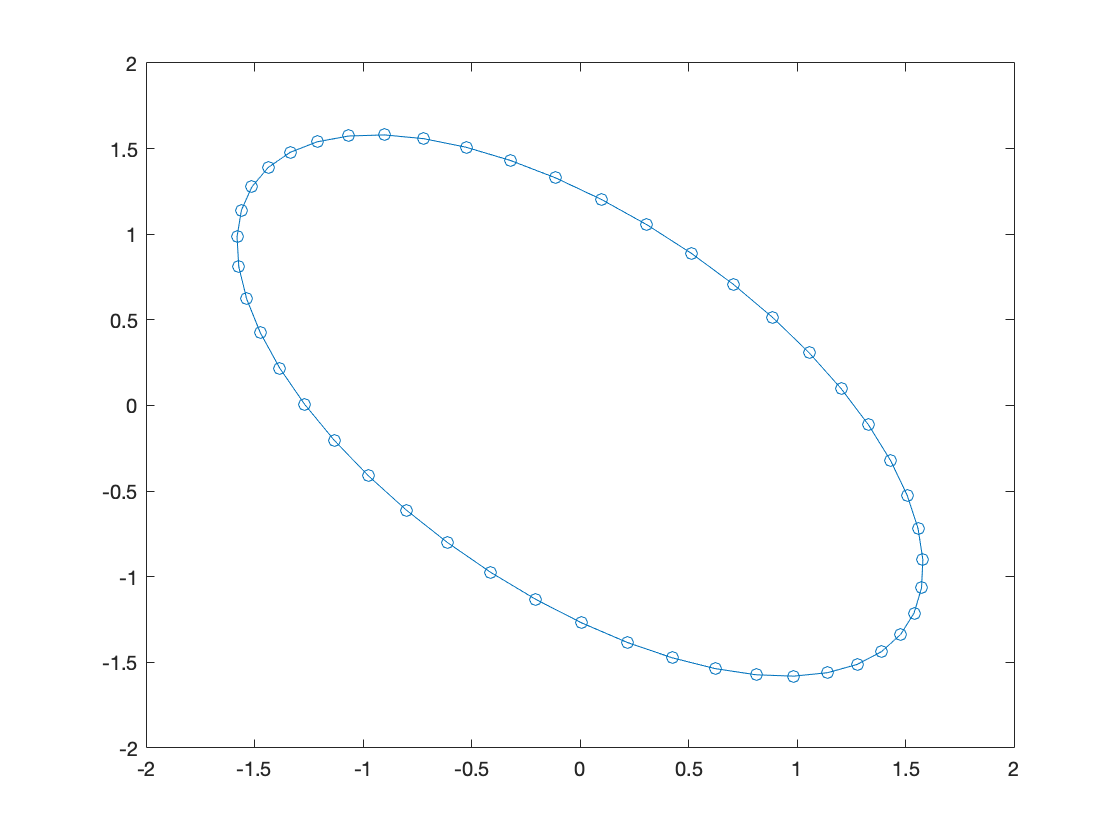

pt = ellipse(1,2,[0 0],48,45); % args: semi axis x, y, center, number of points, angle of rotation
plot(pt(:,1),pt(:,2),'-o')

There's an additional optional last argument called `equal_step`, which, if true, uses the `interparc` third-party function (available from [here](https://www.mathworks.com/matlabcentral/fileexchange/34874-interparc)) to distribute the points unifromly along the boundary.

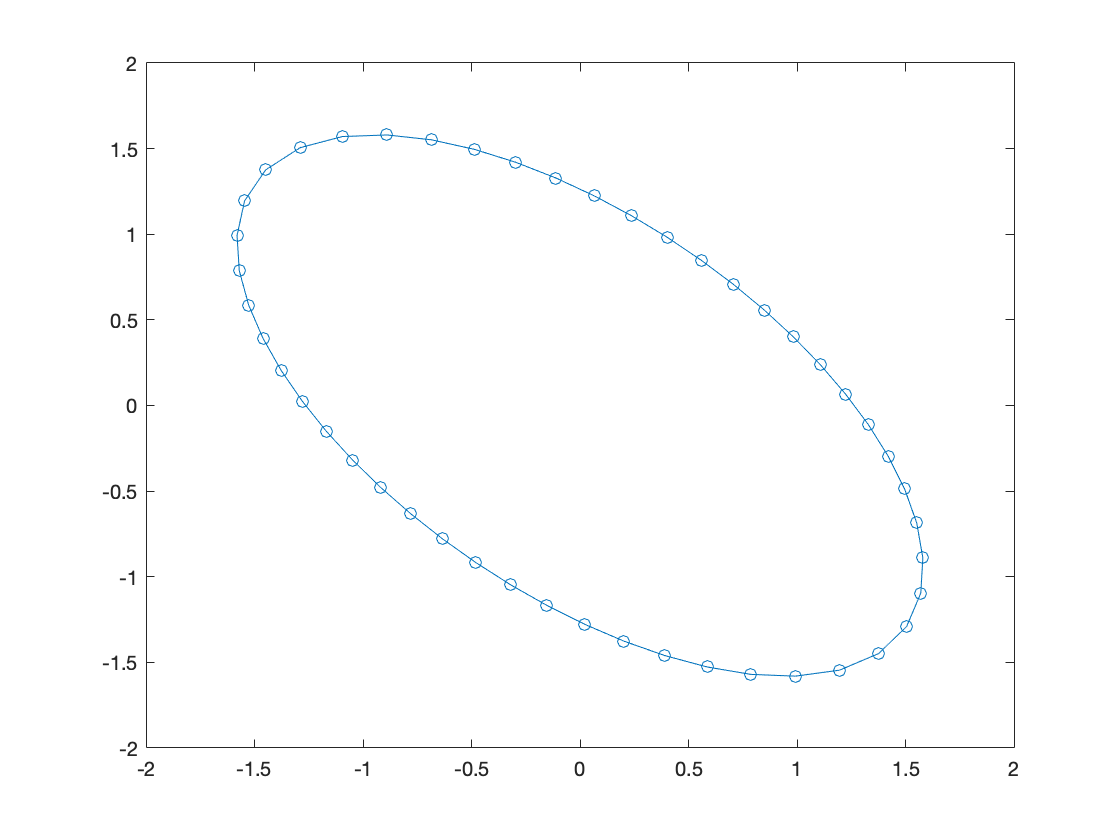

pt = ellipse(1,2,[0 0],48,45,true); % args: semi axis x, y, center, number of points, angle of rotation, equal_step
plot(pt(:,1),pt(:,2),'-o')

 `rectbox` works in much of the same way. 

Let's define a structure similar to the one of example`.png`, using these two functions. It consists of two circles and one rectangle. Note that number of points and `equal_step` are to be defined not in individual `struct`'s, but as `genGDS` arguments and will be applied to all shapes generated with `ellipse`. The definition of an adjacency matrix is critical here, as the inner circle has to be subtracted from the outer. The center coordinates are defined with respect to the middle point of the unit cell.

circ1 = struct('r', [1 1], 'c', [0 0], 'fun', 'ellipse', 'angle', 0); % outer circle, 'r' can be a scalar here
circ2 = struct('r', .8, 'c', [0 0], 'fun', 'ellipse', 'angle', 0); % inner circle
box1 = struct('r', [1.2 .3], 'c', [0 0], 'fun', 'rectbox', 'angle', 0);
A = sparse(false(3)); % doesn't have to sparse, but it's easier to view
A(2,1) = true; % inner circle is in position 2 of the array below, outer -- 1
genGDS('fname', '!ex3_1', 'geom', [circ1,circ2,box1], 'period', 2.5, 'pts', 64, 'uniform_boundary', 1, 'A', A);

Our shapes are assigned to the same structure, as they are not siloed into different (Matlab's) cells. This has default values for `ispost`, which is `true`, meaning that the encircled regions correspond to material (higher index one at least), and `shading`, which is `posts`, i.e. material as well. The opposite mask can be obtained by flipping one of these parameters' values.

An important thing this enables us to do is to define custom functions (see manual for details). Here's an example:

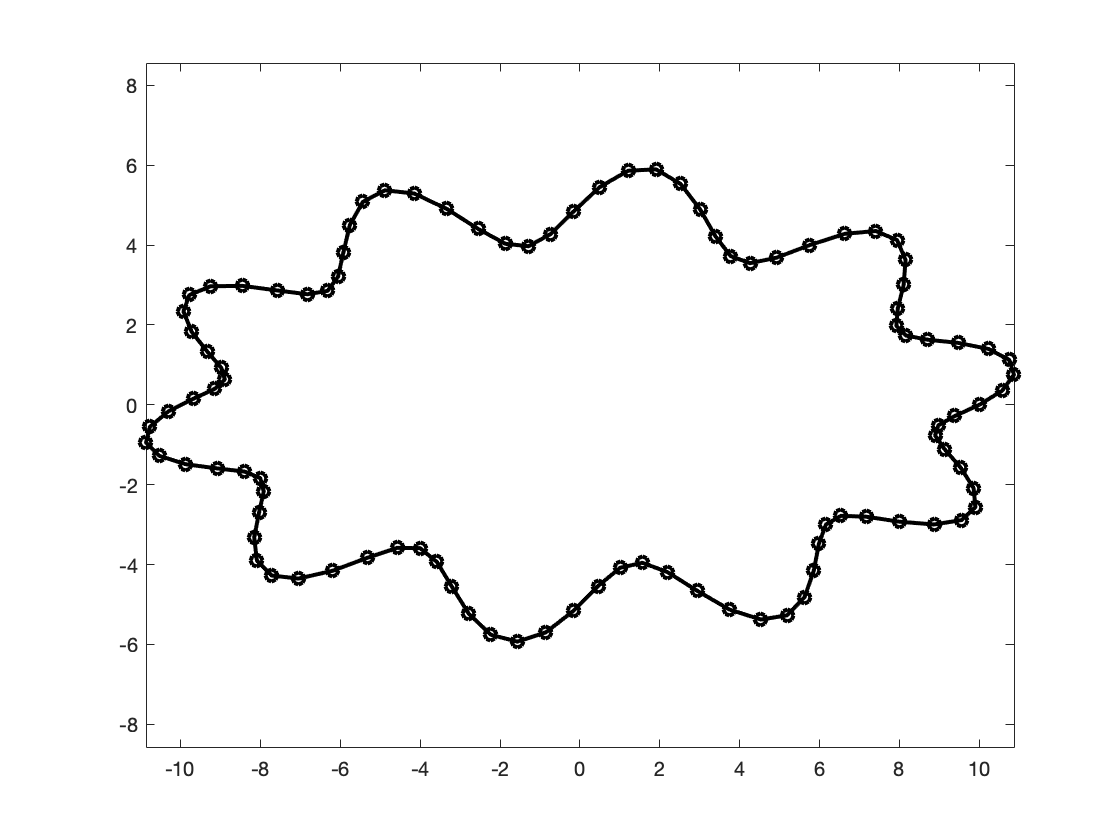

N = 100; % number of points
theta = linspace(0, 2*pi, N).';
myfun = @(r,x,c) [(r(1)+x*sin(10*theta)).*cos(theta) + c(1), (r(end)+x*sin(10*theta)).*sin(theta) + c(2)]; 
pt = myfun([10 5], 1, [0 0]);
plot(pt(:,1),pt(:,2),'-o'); axis equal

And now, to the gds. The `'r'` field has a special meaning now: it is a cell array of all arguments, whatever they may be, in the order they appear in the function definition, except for the last one, which is the coordinates of the center, `c`. `gen_gds_structure` will run something like `myfun(s.r{:}, s.c)`. Notice that we can omit fields `angle` and `c` to have zeros by default. However, be careful, Matlab will fail to contatenate structs with unequal set of fields. Notice also the important set of extra squiggly brackets to prevent Matlab from unpacking the cell array. This can be also achieved with dot assignment, e.g. `s.r = {1,2,3}`.

% s = struct('r', {[10 5], 1}, 'fun', myfun); % array of two structs, not what we want
s = struct('r', {{[10 5], 1}}, 'fun', myfun); % single struct
genGDS('fname', '!ex3_2', 'geom', s, 'period', 12, 'type', 'cyl', 'Rmax', 12);

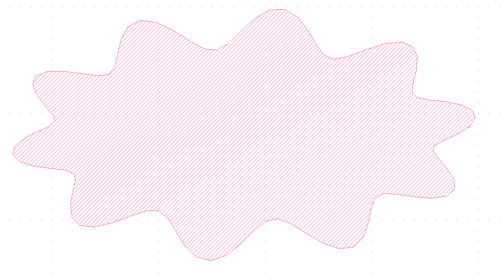

## Example 4: Metasurface layouts

This example demonstrates the role of the `type` parameter. 

To start off, let's define a few different unit cells (four, actually):

ucells = cell(1,4);
% Unit cell #1: four circles of different size
ucells{1} = struct('r',{1,5,2,4},'c',{[5 5],[-5 5],[-5 -5],[5 -5]},'angle',0,'fun','ellipse'); % 1x4 struct array
% Unit cell #2: four ellipses with an angle
ucells{2} = struct('r',[2,4],'c',{[5 5],[-5 5],[-5 -5],[5 -5]},'angle',{-45,45,135,-135},'fun','ellipse'); % 1x4 struct array
% Unit cell #3: simple square
ucells{3} = rectbox(10);
% Unit cell #4: image
ucells{4} = imread('example.png');
P = 20; % period (square, for simplicity)
genGDS('fname', '!ex4_1','geom',ucells,'period',P,'type','cyl','Rmax',P.*[4 3]); 

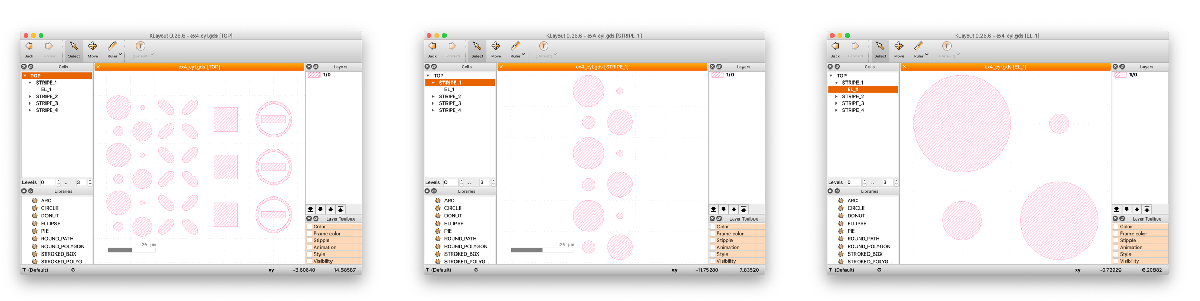

Visually, both `cyl` and `cyl2cart` are identical. The difference is only in internal structure: `cyl2cart` defines pixels as individual references, `cyl` defines 'stripes' (middle image) as a vector of references to a basic cell (right image), then references these stripes to build the mask (left image). 

We can define a deflector in a number of ways by specifying the phase gradient function. One would be:

numcells = 4; % number of different unit cells per zone
phi0 = linspace(0,2*pi,numcells+1);
phi0 = phi0(1:numcells);
P = 20; % unit cell period
rep = 3; % number of repetitions of each unit cell
mult = 11; % number of zones to write'
mult_y = 4; % number of cells in y (invariant) dimension
Rmax = [rep * P * numcells * mult, P * mult_y];
phase_data = @(R) (mod(floor(R/P/rep),numcells)+1/2)/numcells*2*pi;
genGDS(phase_data,'fname','!ex4_2','type','cyl','Rmin',0,'Rmax',Rmax,'geom', ucells, 'phi0', phi0,'period', P);

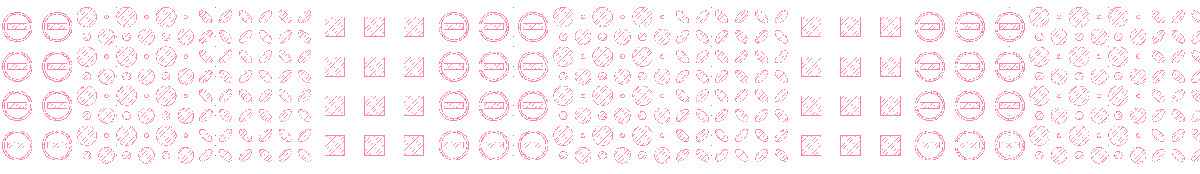

As for the circular metalens, the options are (see more details in the manual):

`circ`

genGDS('fname','!ex4_3','type','circ','Rmin',50,'geom',ucells,'period',P);

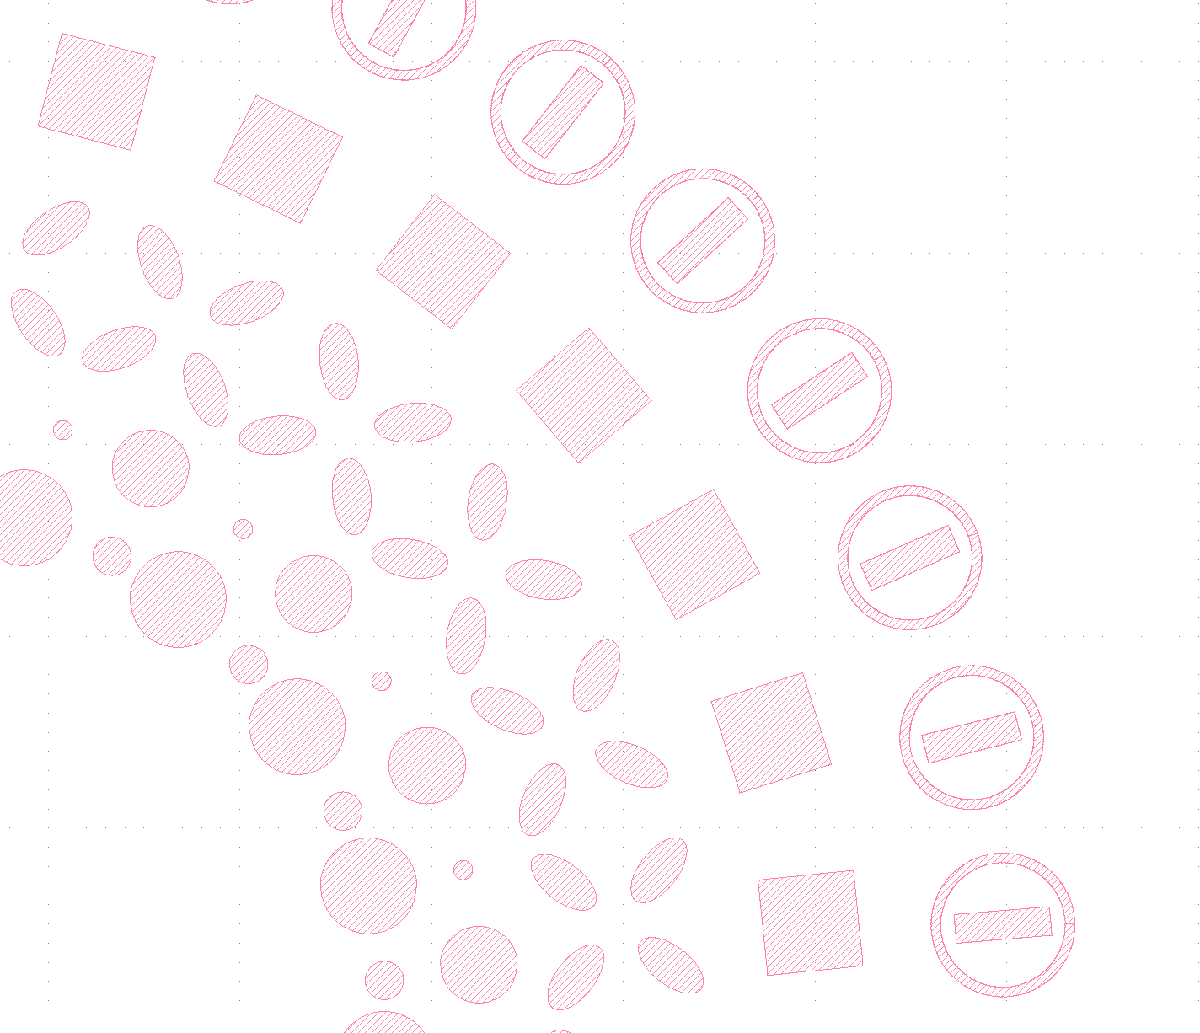

`circ+`

genGDS('fname','!ex4_4','type','circ+','Rmin',50,'geom',ucells,'period',P); 

This option adjusts the positions of the bottom and top halves of the image that shrink and stetch, respectively. This is illustrated schematically below. The right/left part are shown to deform differently, instead of top/bottom, because this section is considered to be positioned at the 0º in the polar coordnates (3 o'clock on a clock face), instead of 90º (12 o'clock).

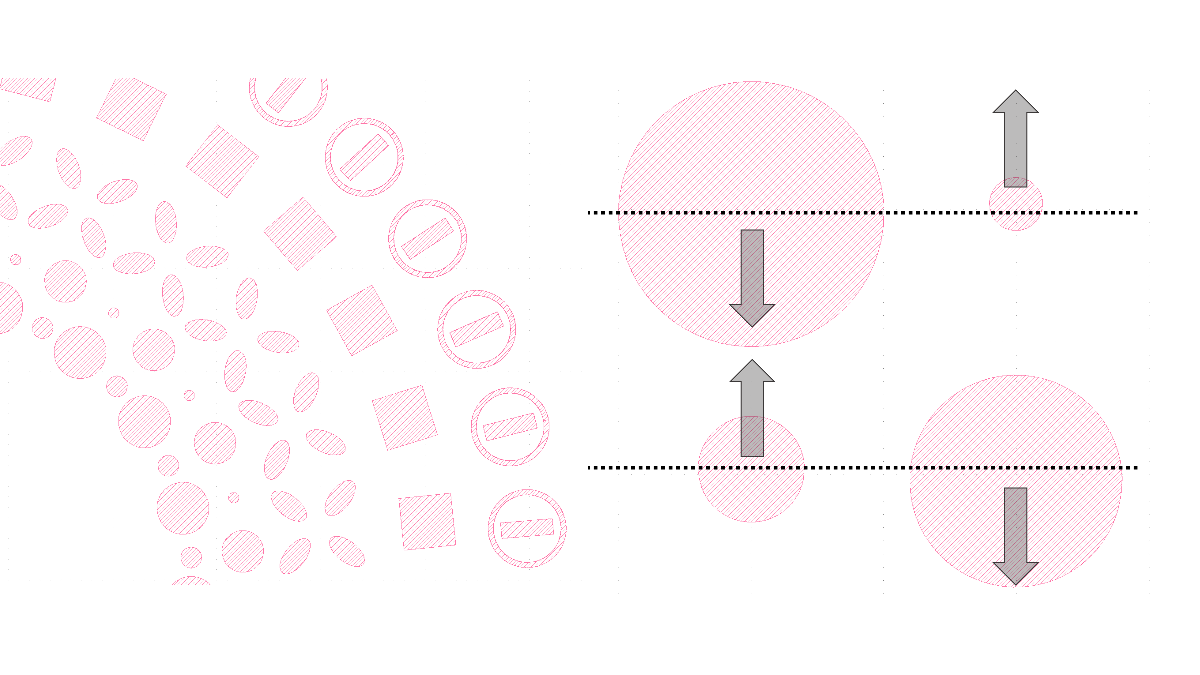

`circ2cart`

genGDS('fname','!ex4_5','type','circ2cart','Rmin',50,'geom',ucells,'period',P);

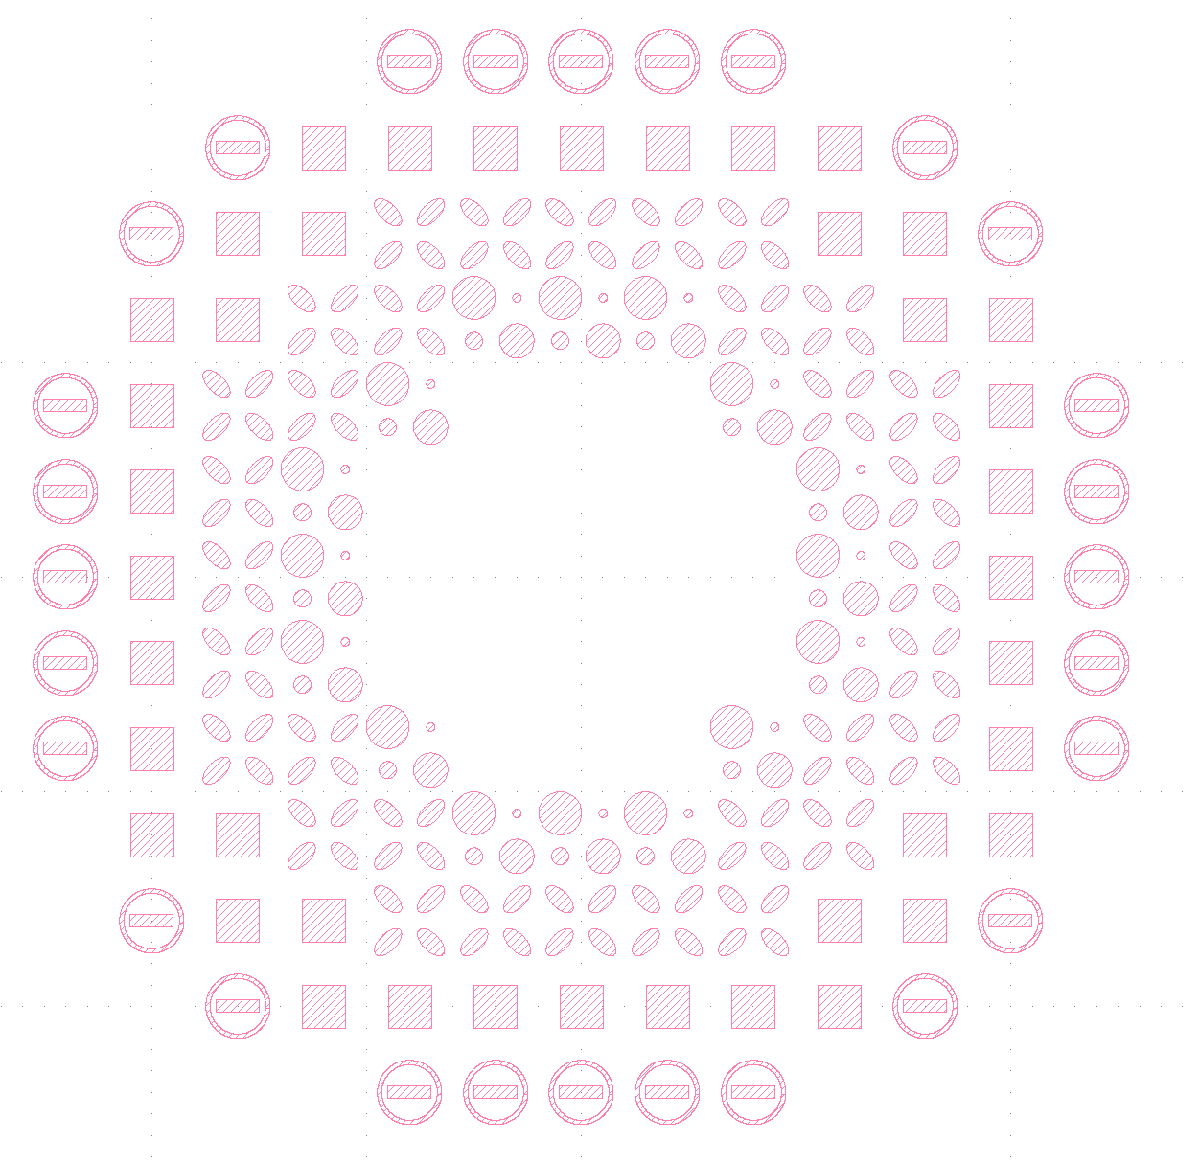

Inverse shading adds a hole in the middle for `circ` and `circ+`, `w`hile for `circ2cart` it doesn't, the idea being that the curvature is not an issue and we can keep `Rmin` zero:

genGDS('fname','!ex4_6','type','circ','Rmin',120,'geom',ucells,'period',P,'shading','holes');

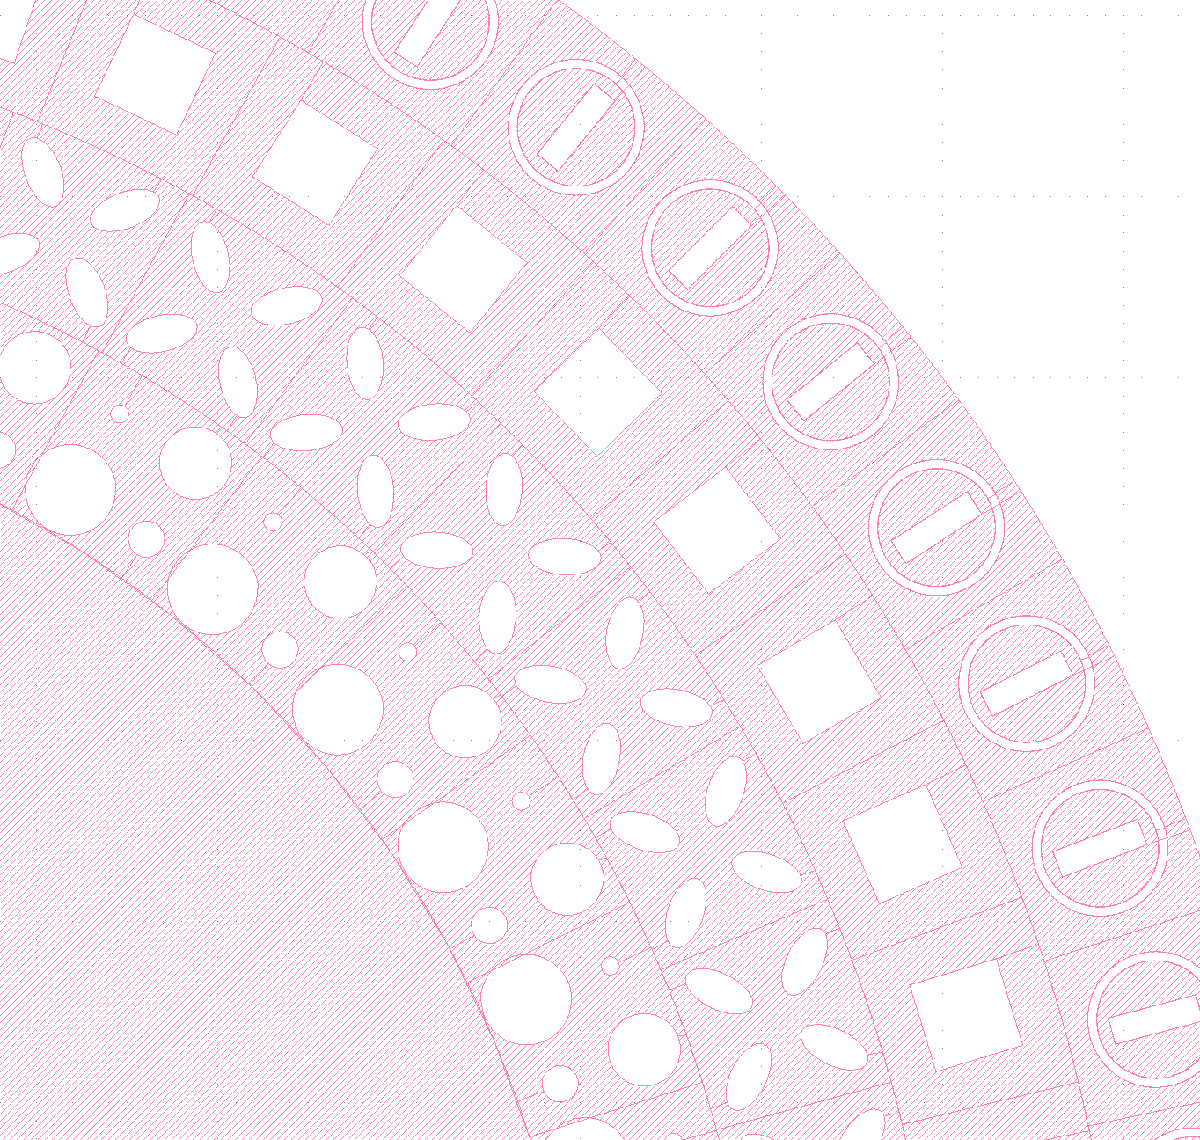

We can flip the unit cell polarity, i.e. in the case of the image, 1s mark air holes with `ispost` set to `false`:

genGDS('fname','!ex4_7','type','circ','Rmin',120,'geom',ucells,'period',P,'shading','holes','ispost',false);

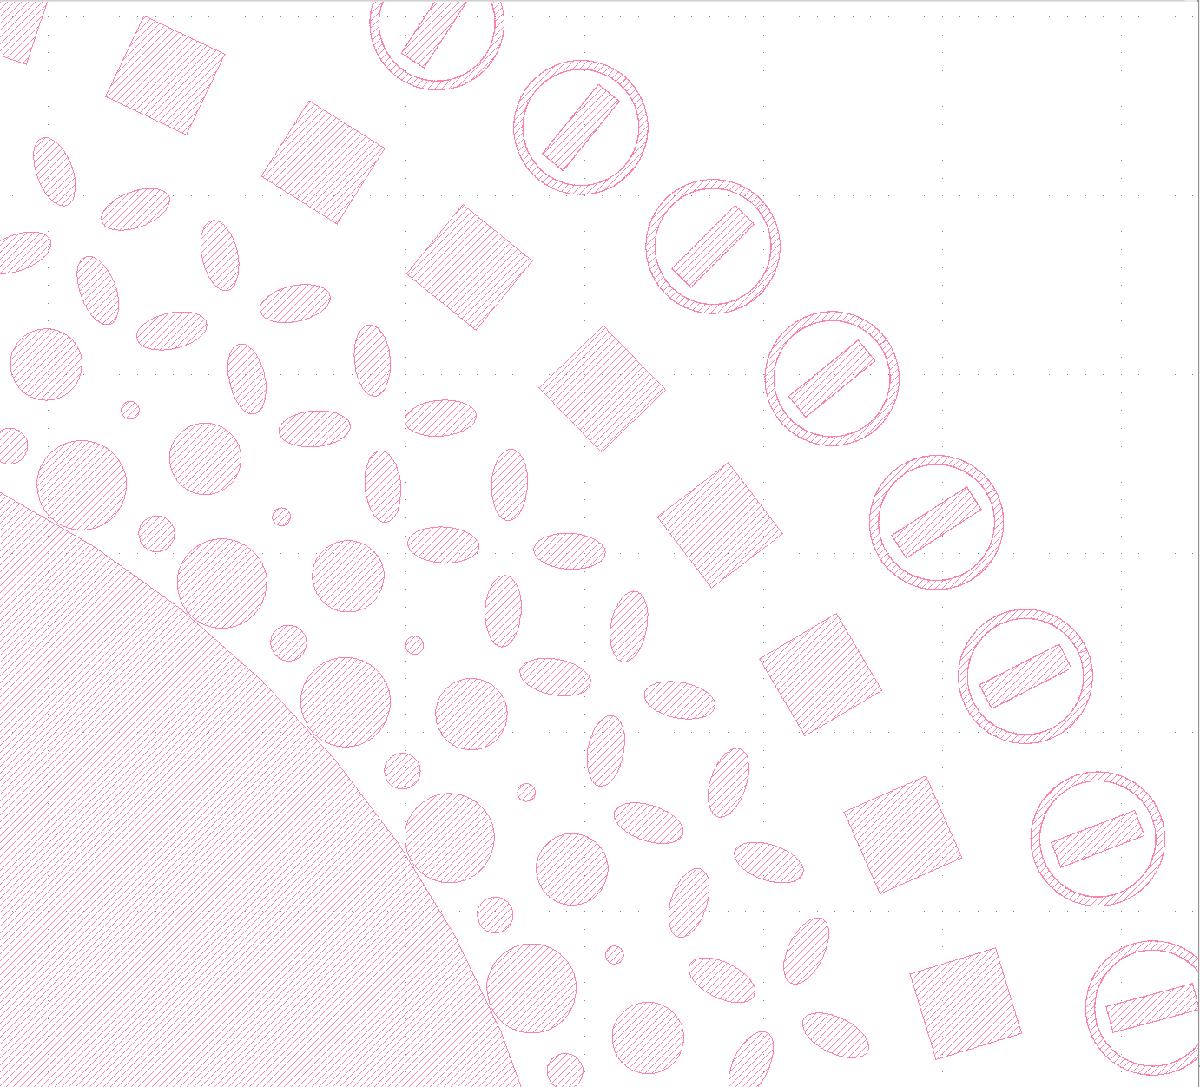

## Example 5: Creating a label

A label with the name of the structure positioned nearby is a useful reference during an experiment. For it to be easily resolvable, but also manufacturable, it is automatically superimposed with a checkerboard pattern. Let's see how it works and explore a few options.

BW = imread('example.png');
clear opts
opts.fname = '!ex5_1'; % filename
opts.geom = BW; % geometries
opts.period = [20 10]; % size of the unit cell
opts.type = 'cyl'; % same result as with cyl2cart
Nx = 2; % number of prepetitions in x
Ny = 2; % number of prepetitions in y
opts.Rmax = opts.period.*[Nx Ny];
opts.ispost = false; % change polarity to see the unit cell outline
opts.label.string = 'example.png'; % what to write
opts.label.height = 1; % height of letters in the user units (uunit)
opts.label.max_feature = 0.08; % largest feature, which is the square diameter
opts.label.location = 'ne'; % top right corner, north-east
opts.label.mirror = true; % duplicate the label on the opposite side upside down
opts.label.angle = 0; % text rotation
genGDS(opts);

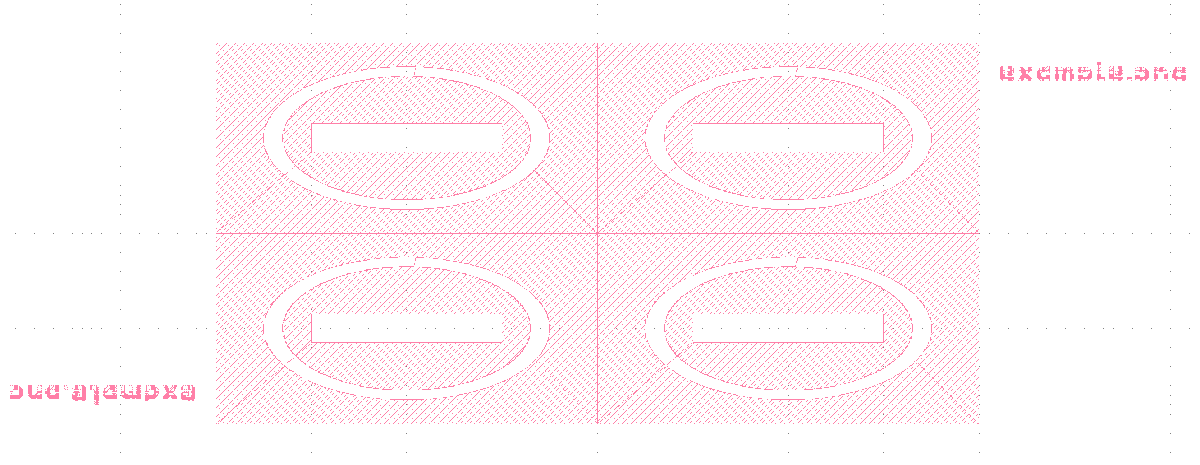

If we zoom into the label, we will see the pattern:

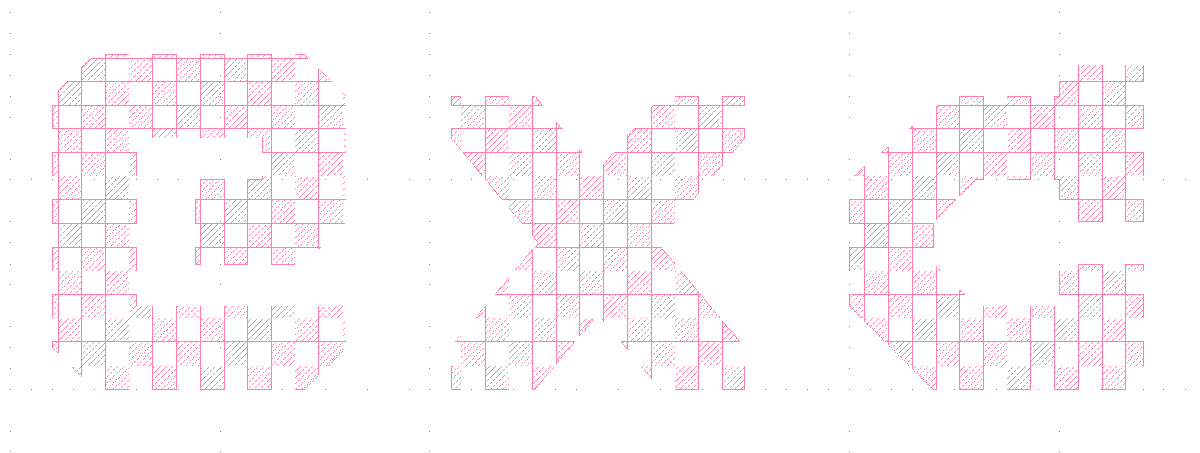

Other location options are available, such as, `nw` (north-west) for upper-left corner

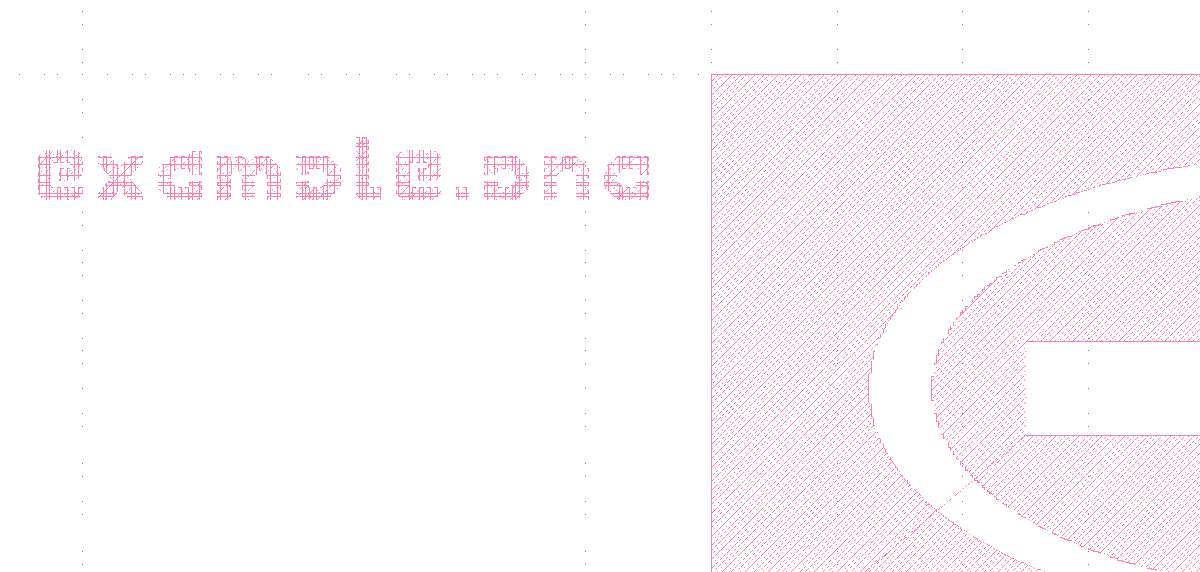

or `out` to put it right outside the box in the corner (inside for circular structures, as corners are empty)

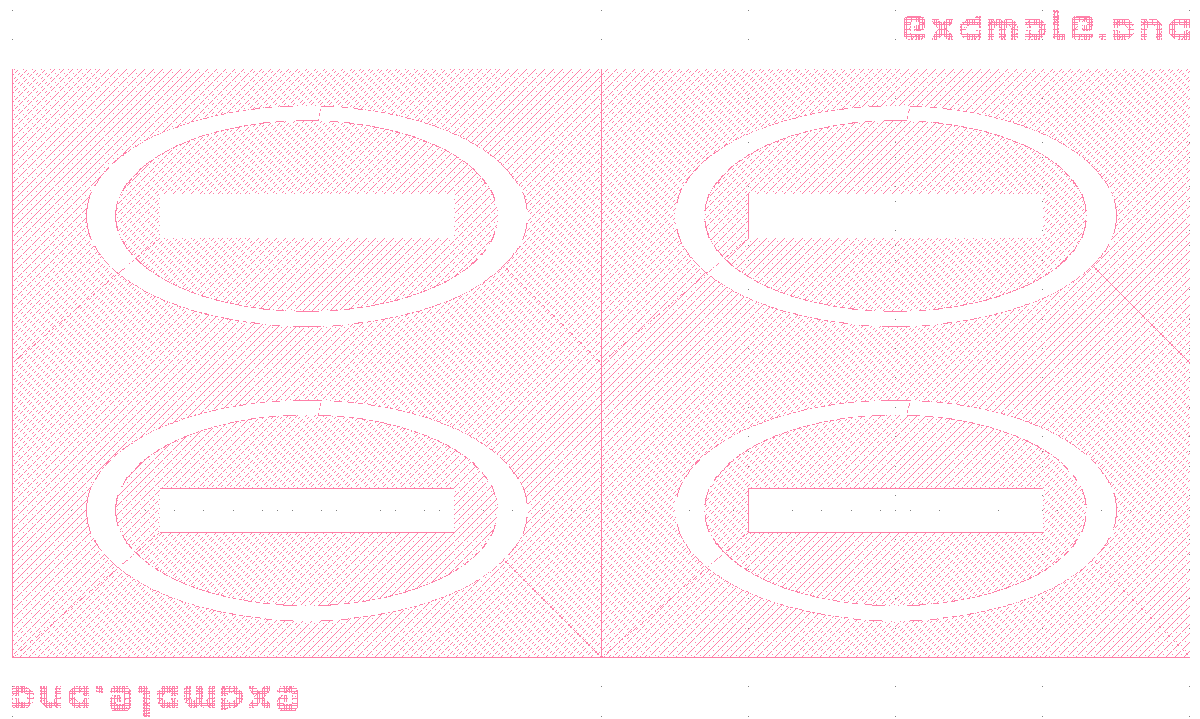

or `center` to position the text right above (below for mirrored) the structure:

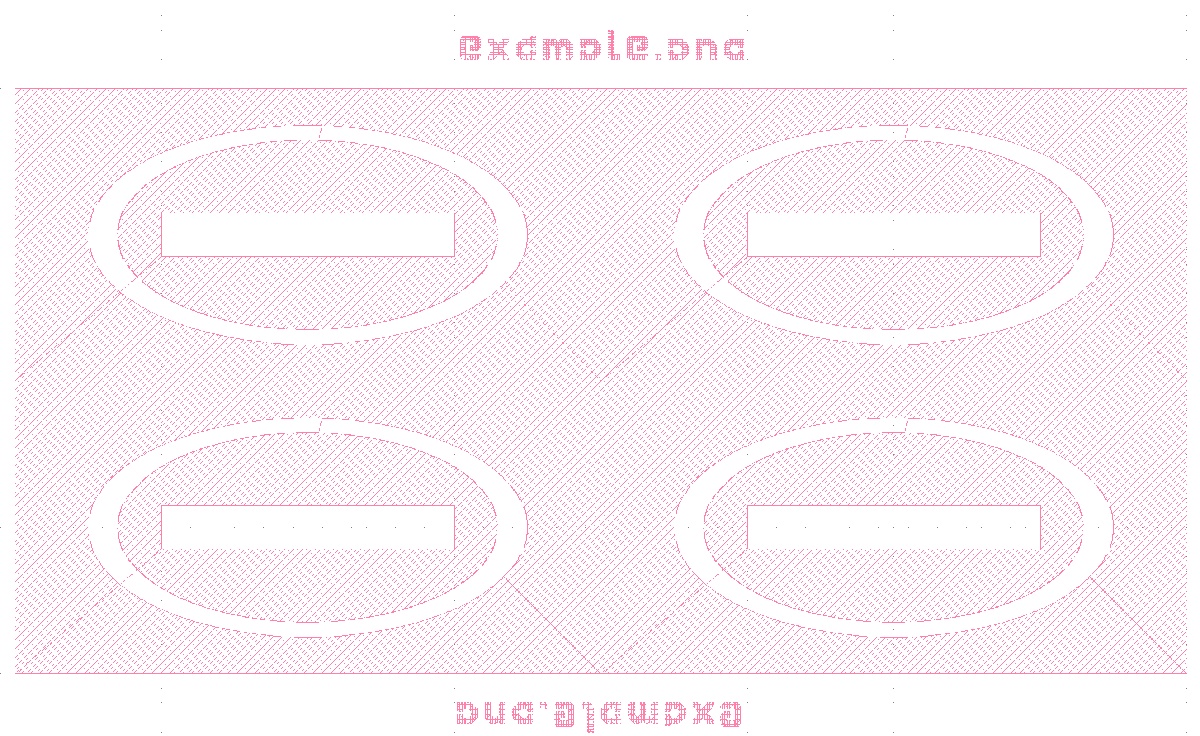

In addition, `position` can be a two element vector with x and y coordinates of the text bottom left corner.

Finally, one example with a circular metasurface. Using the same unit cells as before

ucells = cell(1,4);
% Unit cell #1: four circles of different size
ucells{1} = struct('r',{1,5,2,4},'c',{[5 5],[-5 5],[-5 -5],[5 -5]},'angle',0,'fun','ellipse'); % 1x4 struct array
% Unit cell #2: four ellipses with an angle
ucells{2} = struct('r',[2,4],'c',{[5 5],[-5 5],[-5 -5],[5 -5]},'angle',{-45,45,135,-135},'fun','ellipse'); % 1x4 struct array
% Unit cell #3: simple square
ucells{3} = rectbox(10);
% Unit cell #4: image
ucells{4} = imread('example.png');
label = struct('string','ex5_2','height',8,'location',[150 150],'max_feature',0.08);
genGDS('fname','!ex5_2','type','circ','Rmin',120,'geom',ucells,'period',20,'label',label);